clear, clc, close all

syms t real
syms p1(t) p2(t) [3 1]
syms v1 v2 [3 1] real

d = sqrt(sum( (p1-p2).^2 ))

$$d(t) = \sqrt{{\left(p_{11}\left(t\right)-p_{21}\left(t\right)\right)}^{2}+{\left(p_{12}\left(t\right)-p_{22}\left(t\right)\right)}^{2}+{\left(p_{13}\left(t\right)-p_{23}\left(t\right)\right)}^{2}}$$

1st order


$$\dot{d} = \frac{d}{dt} \sqrt{\sum_{i = 1}^3 (p_{1i} - p_{2i})^2} \\ = \hat{n}^{\top} (v_1 - v_2)$$


其中n是从p2指向p1的单位向量

于是CBF约束为


$$\hat{n}^{\top} (v_1 - v_2) \ge  -\alpha d$$


%% get dereivative of time
% matlab answer
symbolAns = simplify(jacobian(d, t))

$$symbolAns(t) = \begin{array}{l} \frac{2\,\left(\frac{\partial }{\partial t}p_{11}\left(t\right)-\frac{\partial }{\partial t}p_{21}\left(t\right)\right)\,\sigma_{3}+2\,\left(\frac{\partial }{\partial t}p_{12}\left(t\right)-\frac{\partial }{\partial t}p_{22}\left(t\right)\right)\,\sigma_{2}+2\,\left(\frac{\partial }{\partial t}p_{13}\left(t\right)-\frac{\partial }{\partial t}p_{23}\left(t\right)\right)\,\sigma_{1}}{2\,\sqrt{{\sigma_{3}}^{2}+{\sigma_{2}}^{2}+{\sigma_{1}}^{2}}}\\ \mathrm{where}\\ \sigma_{1}=p_{13}\left(t\right)-p_{23}\left(t\right)\\ \sigma_{2}=p_{12}\left(t\right)-p_{22}\left(t\right)\\ \sigma_{3}=p_{11}\left(t\right)-p_{21}\left(t\right) \end{array}$$

% our result
n = (p1-p2)/d; % unit vector pointing from p2 to p1
myAns = sum(n .* (jacobian(p1, t) - jacobian(p2, t)))

$$myAns(t) = \begin{array}{l} \frac{\left(\frac{\partial }{\partial t}p_{11}\left(t\right)-\frac{\partial }{\partial t}p_{21}\left(t\right)\right)\,\left(p_{11}\left(t\right)-p_{21}\left(t\right)\right)}{\sigma_{1}}+\frac{\left(\frac{\partial }{\partial t}p_{12}\left(t\right)-\frac{\partial }{\partial t}p_{22}\left(t\right)\right)\,\left(p_{12}\left(t\right)-p_{22}\left(t\right)\right)}{\sigma_{1}}+\frac{\left(\frac{\partial }{\partial t}p_{13}\left(t\right)-\frac{\partial }{\partial t}p_{23}\left(t\right)\right)\,\left(p_{13}\left(t\right)-p_{23}\left(t\right)\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left(p_{11}\left(t\right)-p_{21}\left(t\right)\right)}^{2}+{\left(p_{12}\left(t\right)-p_{22}\left(t\right)\right)}^{2}+{\left(p_{13}\left(t\right)-p_{23}\left(t\right)\right)}^{2}} \end{array}$$

% they are the same
simplify(symbolAns - myAns)

$$ans(t) = 0$$

2nd order

TODO， very interesting

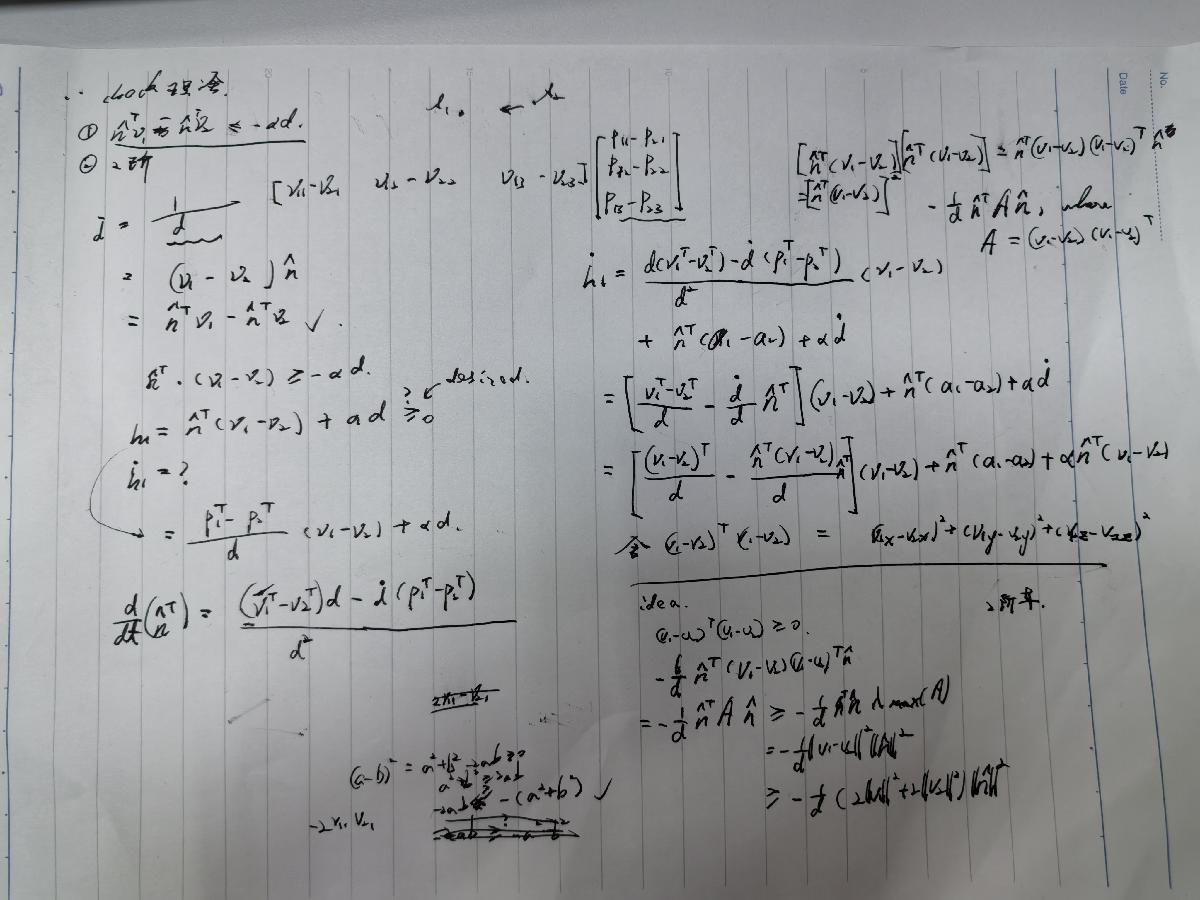

syms alpha real
d_dot = sum(n .* (v1 - v2))

$$d\_dot(t) = \begin{array}{l} \frac{\left(p_{11}\left(t\right)-p_{21}\left(t\right)\right)\,\left(v_{11}-v_{21}\right)}{\sigma_{1}}+\frac{\left(p_{12}\left(t\right)-p_{22}\left(t\right)\right)\,\left(v_{12}-v_{22}\right)}{\sigma_{1}}+\frac{\left(p_{13}\left(t\right)-p_{23}\left(t\right)\right)\,\left(v_{13}-v_{23}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left(p_{11}\left(t\right)-p_{21}\left(t\right)\right)}^{2}+{\left(p_{12}\left(t\right)-p_{22}\left(t\right)\right)}^{2}+{\left(p_{13}\left(t\right)-p_{23}\left(t\right)\right)}^{2}} \end{array}$$

h1 = d_dot + alpha * d

$$h1(t) = \begin{array}{l} \alpha \,\sigma_{1}+\frac{\left(p_{11}\left(t\right)-p_{21}\left(t\right)\right)\,\left(v_{11}-v_{21}\right)}{\sigma_{1}}+\frac{\left(p_{12}\left(t\right)-p_{22}\left(t\right)\right)\,\left(v_{12}-v_{22}\right)}{\sigma_{1}}+\frac{\left(p_{13}\left(t\right)-p_{23}\left(t\right)\right)\,\left(v_{13}-v_{23}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left(p_{11}\left(t\right)-p_{21}\left(t\right)\right)}^{2}+{\left(p_{12}\left(t\right)-p_{22}\left(t\right)\right)}^{2}+{\left(p_{13}\left(t\right)-p_{23}\left(t\right)\right)}^{2}} \end{array}$$



expand((v1 - v2)' * (v1 - v2))

$$ans = {v_{11}}^{2}-2\,v_{11}\,v_{21}+{v_{12}}^{2}-2\,v_{12}\,v_{22}+{v_{13}}^{2}-2\,v_{13}\,v_{23}+{v_{21}}^{2}+{v_{22}}^{2}+{v_{23}}^{2}$$

simplify(eig((v1 - v2) * (v1 - v2)'))

$$ans = \left(\begin{array}{c} 0\\ 0\\ {v_{11}}^{2}-2\,v_{11}\,v_{21}+{v_{12}}^{2}-2\,v_{12}\,v_{22}+{v_{13}}^{2}-2\,v_{13}\,v_{23}+{v_{21}}^{2}+{v_{22}}^{2}+{v_{23}}^{2} \end{array}\right)$$